# 1D optimisation of droplet center

#### To generate optimisation procedure for the *(center of the)* initial droplet location

- Select variables for droplet and chose Target Shape

- Plot initial droplet shape based on chosen `x0`

- Use optimisation prosidure to find bes possition of droplet

clear; clc;

## **1) **

**Set some values**

y0 = .1084434390; % Raise droplet profile...
N = 100; % # sample points
A = 21; % Magnitude/Amplitude of droplet

xMax = 10; 
dx = 2*xMax/(N-1); % Stepsize
X = -xMax:dx:xMax; % Linespace/Mesh
k = 1/(2*xMax/N); %omega
var = [A;N;k;y0]; 

% Set time span
tfinal = 10^5; % final time >> 1
tSpan = [1e-6 tfinal]; 

% Possition / Shift
x0 = 4;
% x0 = 2;

% Fixxed Disjoinning pressure
% c0(1) = 0.0002;  
% c0(2) = 0.0046;
c0(1) = 0.001;  
c0(2) = 0.023;

% Condition
conds0 = [x0,c0(1),c0(2)];

% Creating test matrix to soolve ODE
D1 = full(gallery('tridiag',N,-1,0,1));
D1(N,1)=1;D1(1,N)=-1;
D1 = D1/(2*dx);
D1 = sparse(D1); % D1
D2 = full(gallery('tridiag',N,1,-2,1));
D2(N,1)=1;D2(1,N)=1;
D2 = D2/dx^2;
D2 = sparse(D2); % D2

**Target Shape **`h_target`

h_target = 0.1*ones(size(X));
h_target(2.5 - X.^2/12>0.1) = 2.5 - X(2.5 - X.^2/12>0.1).^2/12;
% Target shape is a parabola, not achievable

## **2) **

**Initial droplet centered around **`x0`

h0 = hFinal(conds0,X,var,D1,D2,tSpan);
H0 = deval(h0,tfinal); 

## **3)**

**Solution**

% Vertical/Function tolerance: 1e-1
% Horizontal tolerance: 1e-1
options = optimset('Display','iter','TolFun',1e-1,'TolX',1e-1,'MaxFunEvals',4*60,'MaxIter',4*50);

% Generate an object/function to be optimise
myObjective_Possition = @(conds) costEvaluation(conds,X,var,D1,D2,tSpan,tfinal,h_target);
% in this case we have a cost function

figure;

grid on
plot(X,h_target,'k:','linewidth',2);
title('2-D profile of droplet')
xlabel('x')
ylabel('u(x)')
hold on
plot(X,H0,'*r');
ylim([0 5]);

% Solution of best center point: x_sol
[conds_Sol,fval,exitflag,output] = fminsearch(myObjective_Possition,conds0,options);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          123.062         
     1            4          119.604         initial simplex
     2            6          117.842         expand
     3            8          104.062         expand
     4           10          94.5786         expand
     5           12          72.6917         expand
     6           14          49.2883         expand
     7           16          11.6268         expand
     8           18          4.99623         reflect
     9           19          4.99623         reflect
    10           21          4.99623         contract inside
    11           23          4.99623         contract inside
    12           25          4.99623         contract outside
    13           27           4.4932         contract inside
    14           29           4.4932         contract inside
    15           31           4.4932         contract outside
    16           33           4.4932         contr

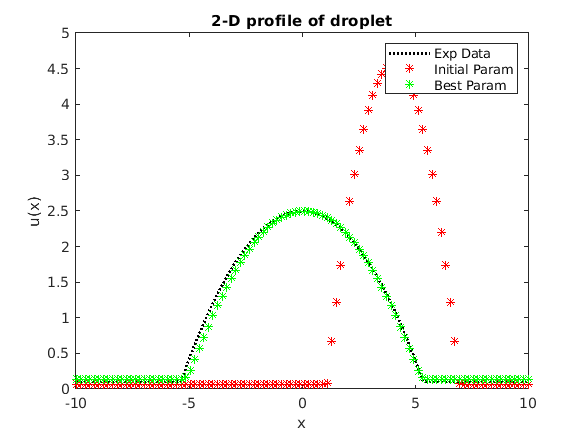


% resulting portfolio
h_Sol = hFinal(conds_Sol,X,var,D1,D2,tSpan);

% resulting final profile (at t = tfinal)
H_Sol = deval(h_Sol,tfinal);

plot(X,H_Sol,'*g')
legend('Exp Data','Initial Param','Best Param');
hold off


conds_Sol

conds_Sol =     0.0349    0.0017    0.0208


fval

fval = 4.4679

exitflag

exitflag = 1

output

output = struct with fields:
    iterations: 21
     funcCount: 43
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 ↵'


% figure;
% n = size(H_Sol);
% m = n(1);
% H_1 = h_Sol.y(:,1);
% H_2 = h_Sol.y(:,m/4);
% H_3 = h_Sol.y(:,3*m/4);
% H_4 = h_Sol.y(:,m);
% plot(X,H_1,'b-',X,H_2,'g-',X,H_3,'y-',X,H_4,'r-')